Fractal scale-free demo: (u,v)-flower self-similarity

Run this live script from the package folder so the helper functions are on the MATLAB path.

clearvars; close all; clc;

%DEMO_SCALEFREE_FRACTAL_UVFLOWER Fractal scale-free example using a (u,v)-flower.
%
% This is the "clean fractal" counterpart to the BA model.
% Choose u > 1 to obtain a finite fractal dimension.

u = 2;
v = 2;


Visualize several generations

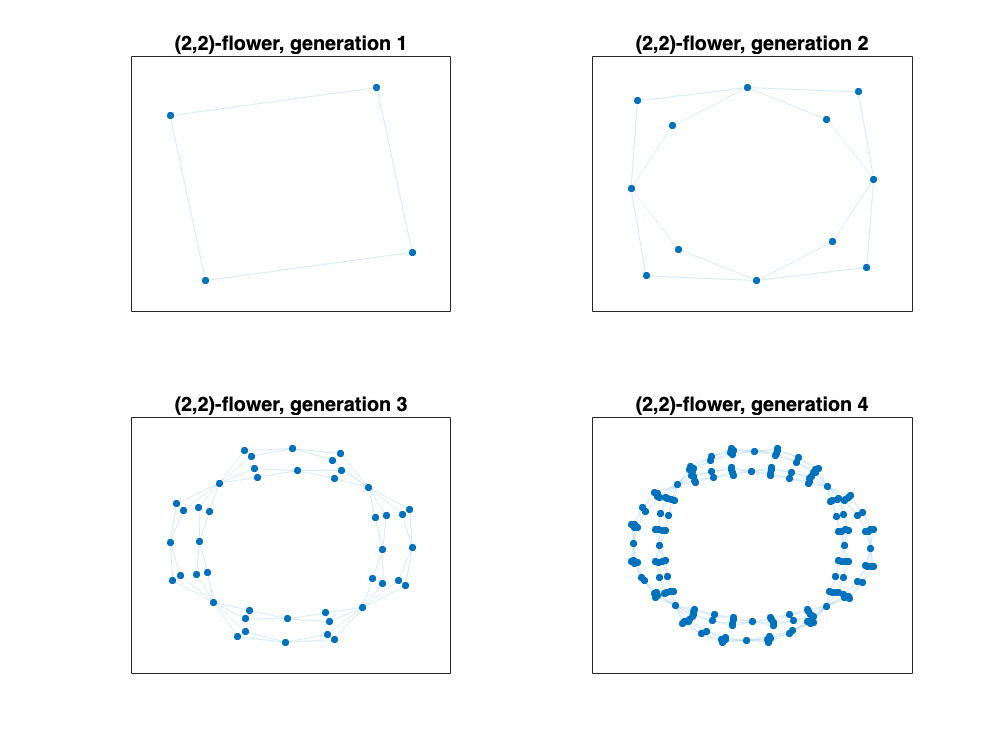

figure('Name', 'Fractal scale-free flower generations');
tiledlayout(2, 2);

for g = 1:4
    G = make_uv_flower(u, v, g);
    nexttile;
    plot(G, 'Layout', 'force', 'NodeLabel', {}, 'MarkerSize', 3, 'EdgeAlpha', 0.15);
    title(sprintf('(%d,%d)-flower, generation %d', u, v, g));
end

Fractal scaling: N versus diameter

gList = 1:5;
N = zeros(size(gList));
D = zeros(size(gList));

for ii = 1:numel(gList)
    G = make_uv_flower(u, v, gList(ii));
    N(ii) = numnodes(G);
    [~, D(ii)] = path_length_stats(G, false);
end

fitCoeff = polyfit(log(D(:)), log(N(:)), 1);


Degree CCDF of a larger generation

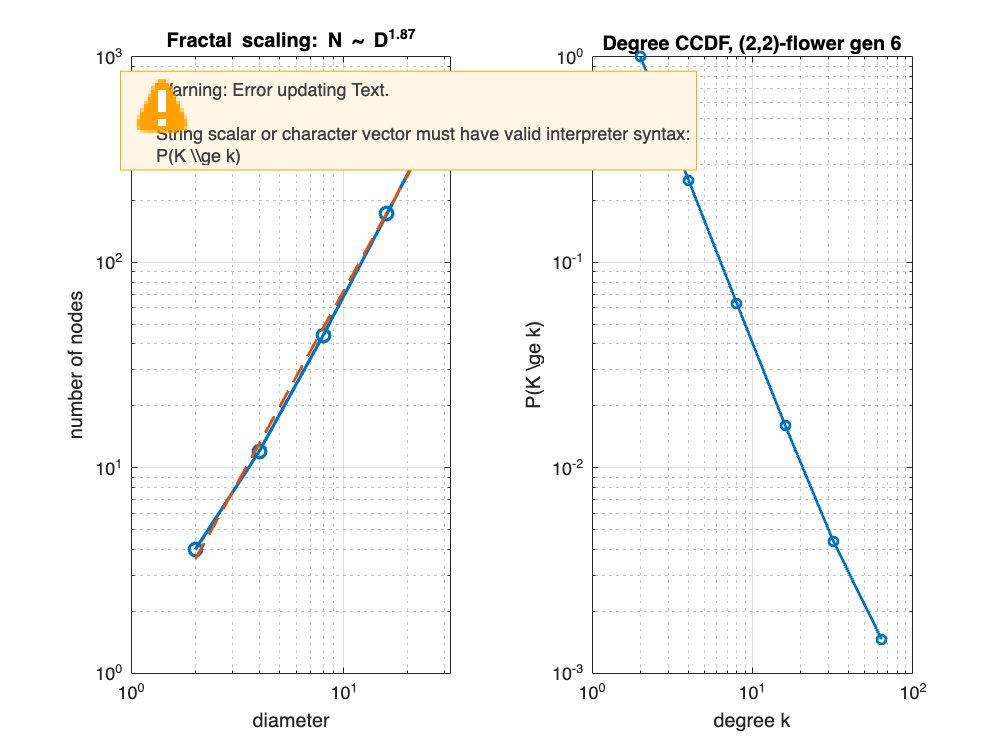

Gbig = make_uv_flower(u, v, 6);
k = degree(Gbig);
[x, ccdf] = empirical_ccdf(k);

figure('Name', 'Fractal scale-free flower scaling');
tiledlayout(1, 2);

nexttile;
loglog(D, N, 'o-', 'LineWidth', 1.8, 'MarkerSize', 7);
hold on;
loglog(D, exp(polyval(fitCoeff, log(D(:)))), '--', 'LineWidth', 1.6);
hold off;
xlabel('diameter');
ylabel('number of nodes');
title(sprintf('Fractal scaling: N ~ D^{%.2f}', fitCoeff(1)));
grid on;

nexttile;
loglog(x, ccdf, 'o-', 'LineWidth', 1.5, 'MarkerSize', 5);
xlabel('degree k');
ylabel('P(K \ge k)');
title(sprintf('Degree CCDF, (%d,%d)-flower gen 6', u, v));
grid on;


gammaTheory = 1 + log(u + v) / log(2);
dBTheory = log(u + v) / log(u);

fprintf('\nFractal scale-free demo finished.\n');


Fractal scale-free demo finished.


fprintf('Using the deterministic (%d,%d)-flower:\n', u, v);

Using the deterministic (2,2)-flower:


fprintf('  Theoretical degree exponent gamma = %.3f\n', gammaTheory);

  Theoretical degree exponent gamma = 3.000


fprintf('  Theoretical fractal dimension d_B = %.3f\n', dBTheory);

  Theoretical fractal dimension d_B = 2.000


fprintf('  Estimated d_B from N vs D = %.3f\n\n', fitCoeff(1));

  Estimated d_B from N vs D = 1.868

